# Microgrid Design and Control

## 1. Overview

This microgrid model integrates multiple renewable energy sources including solar PV, wind turbines, and a Battery Energy Storage System. The microgrid controller is designed in compliance with IEEE Standard 2030.7 and IEEE Standard 2030.8. Each source is implemented as a modular component with its own documentation page and a dedicated test harness for isolated tuning.

The modular approach accelerates development by allowing you to configure and validate each component independently before integrating it into the larger microgrid system. 

## 2. Model Architecture

This model consists of several components like wind, solar, BESS. Each component is configurable and designed for easy scaling across different power levels.

                                                                     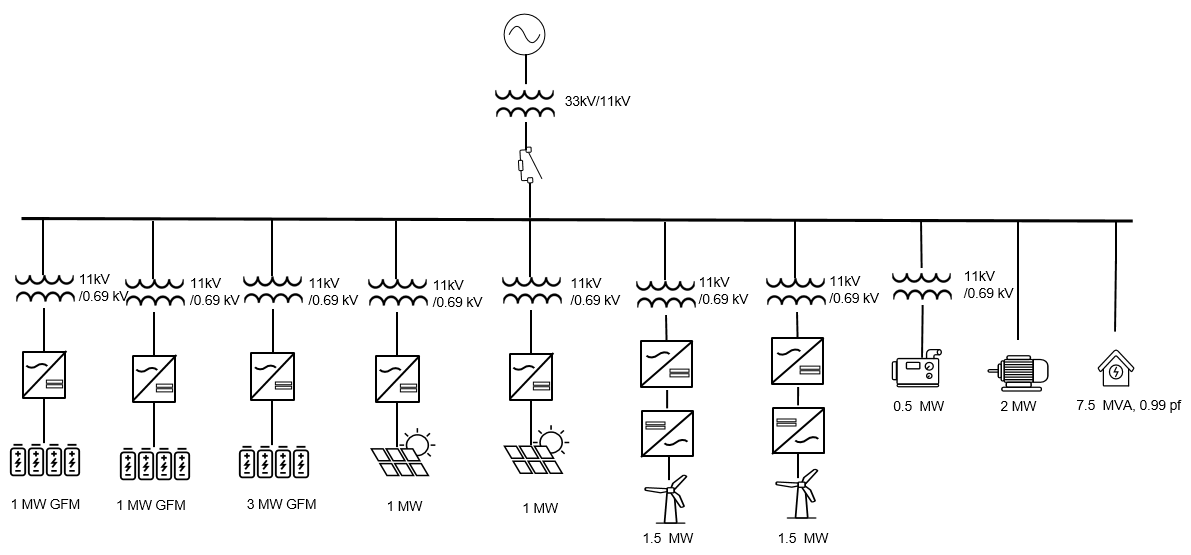            

### Key Components

**Solar PV System**

Implements a grid following inverter with maximum power point tracking and reactive power support. This model contains two 1MW solar plants

**Wind Turbine System**

Implements a Type 4 wind turbine that includes a machine side converter and a grid side converter. This model contains two 1.5 MW wind turbines.

**Battery Energy Storage System**

Operates in grid-forming mode or grid-following. It provides voltage and frequency support and stabilizes the microgrid during disturbances. This model contains two 1 MW BESS units and one 3 MW BESS unit. These BESS units operate in grid-forming mode and can be operated in grid-following mode according to your requirements

**Microgrid Controller**

Implements IEEE compliant dispatch and transition functions such as planned islanding, resynchronization, black start, and load management. 

**Controller Compliance**

- **IEEE Standard 2030.7** defines the controller functions used for power dispatch and operational transitions.

- **IEEE Standard 2030.8** defines the testing procedures for planned islanding, resynchronization, and black start.

For more information on microgrid components, please refer to [Microgrid Components](matlab:openScript('CustomComponents.html'))

For more information on micorgrid controller, please refer to [MicrogridController](matlab:openScript('MicrogridController.html'))

## Microgrid Model

This flow chart gives the steps to build the microgrid model

                                                                         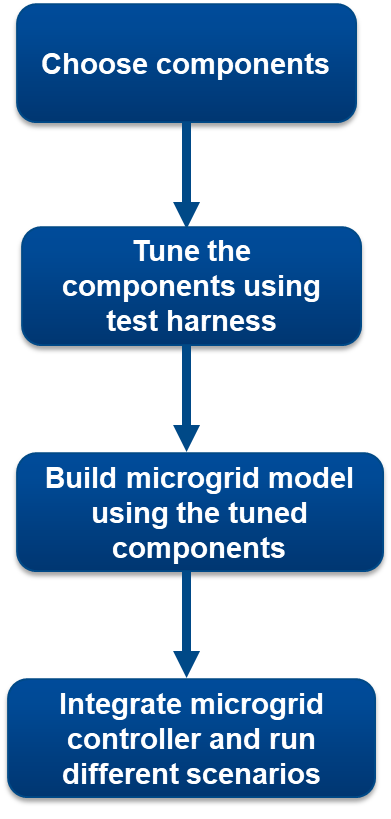

**Step 1 : Tune components**

Adjust each component to the desired **rating and control settings** using the quick checks described in its **Component Brief**. This isolates parameter iteration and avoids whole system reruns.

**Step 2 : Record parameters**

Capture rated power, limits, and controller gains as a parameter set for each component. Keep a short notes file or data sheet per module so updates are traceable.

**Step 3 :  Plug into the larger model**

Populate the subsystem masks in the integrated microgrid model with the tuned parameters. 

**Step 4 : Run system level scenarios**

- **Planned islanding** and **resynchronization** to validate transitions

- **BESS charging and discharging** to validate SOC and power limits

- **Load steps and renewable fluctuations** to verify stability, power sharing, and PQ

**Step 5 : Evaluate performance**

Check steady state error, settling time, and overshoot for voltage and frequency. Verify power quality at the PCC against harmonic goals (THD and TDD) and confirm that dispatch objectives are met under operating constraints.

In this example, micrgrid model is built using these components and integrated with the microgrid controller

                                              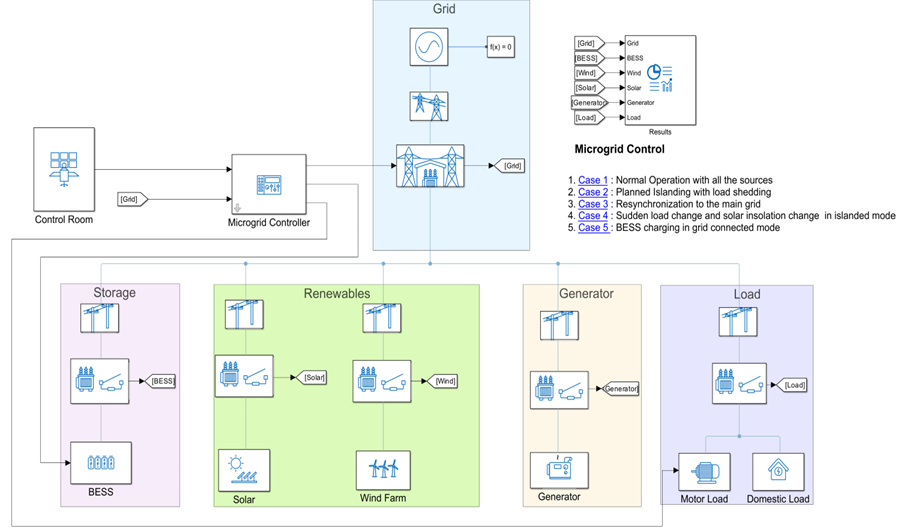

## 5. Simulation Scenarios

### Case 1: Normal Operation

In this scenario. all the generating sources are providing power and the microgrid is operating in grid connected mode with the PCC breaker closed.

You can modify the parameters of the model in [MicrogridControlParam](matlab:open('MicrogridControlParam.m')). Initialize the parameters for case 1 and run the model.

load_system('MicrogridControl');
set_param('MicrogridControl','FastRestart','on');
MicrogridControlParam;
NormalOperation;
simoutData = sim('MicrogridControl','SrcWorkspace','current');

This plot shows the active and reactive power of BESS, grid, PV, wind, and loads. Stable active power output and reactive power outputs indicate a stable control.

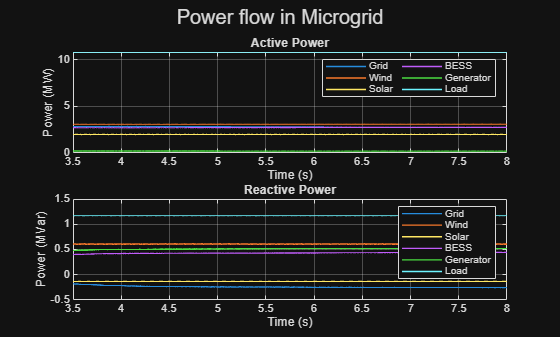

plot.powerFlow(simoutData.logsout,1);

This plot shows the PCC breaker status and the oeprating mode of the microgrid

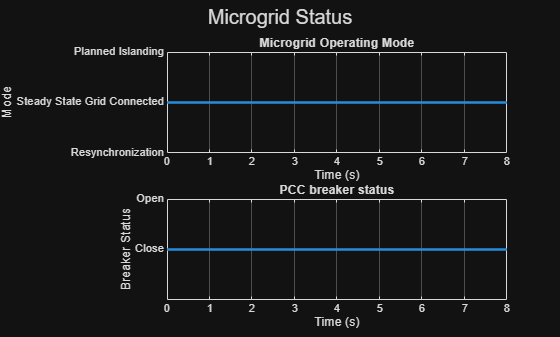

plot.microgridStatus(simoutData.logsout,1);

This plot shows the voltage and current at the loads. Stable load voltage and load during the planned islanding process indicate a stable control.

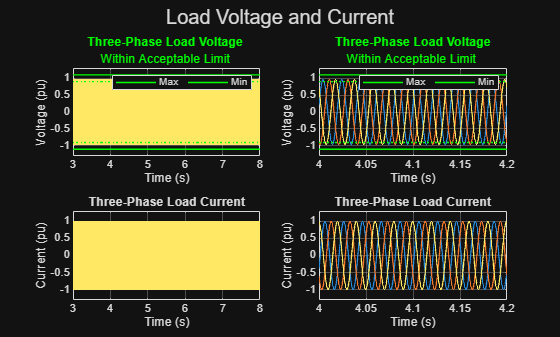

plot.loadVI(simoutData.logsout,'instantaneous',1);

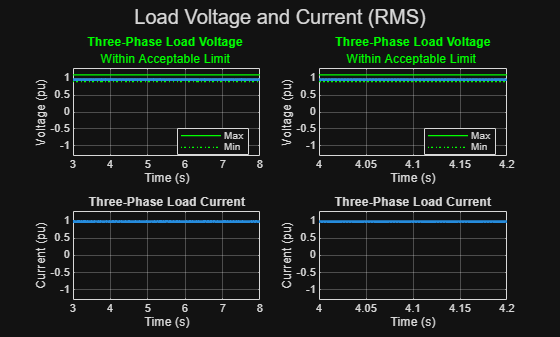

plot.loadVI(simoutData.logsout,'RMS',1);

### Case 2 : Planned Islanding

In this scenario, the microgrid transitions from grid-connected operation to islanded mode in a controlled manner. Once the planned islanding command is initiated, the motor load is disconnected to reduce stress on the system. The controller monitors the power flow at the point of common coupling (PCC), and when the grid power drops below the defined threshold, the PCC breaker opens to isolate the microgrid.

Initialize the parameters for case 2 and run the model.

PlannedIslandingControl;
simoutData = sim("MicrogridControl",'SrcWorkspace','current');

This plot shows the active and reactive power of BESS, grid, PV, wind, and loads. Stable active power output and reactive power outputs indicate a stable control.

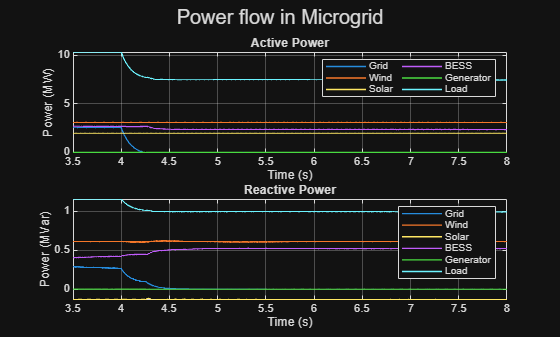

plot.powerFlow(simoutData.logsout,2);

This plot shows the islanding command, islanding, and the breaker status signals in the first subplot. The Islanding and BRK Status signals are high when the power flow from the grid is equal to zero

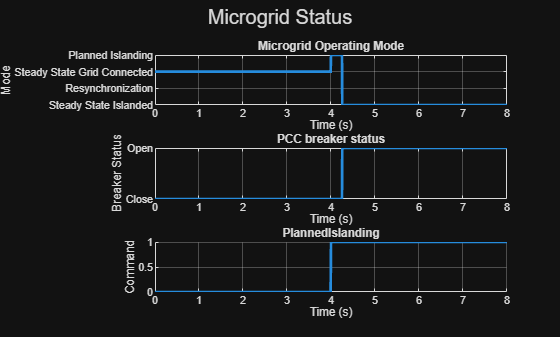

plot.microgridStatus(simoutData.logsout,2);

This plot shows the voltage and current at the loads. Stable load voltage and load during the planned islanding process indicate a stable control.

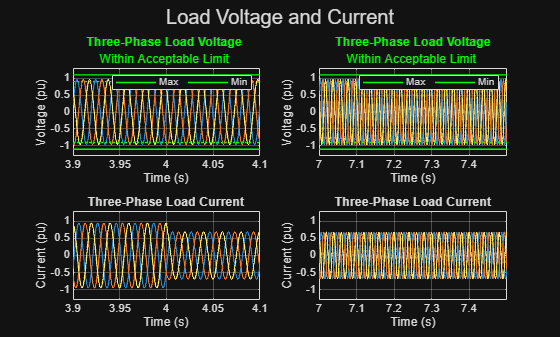

plot.loadVI(simoutData.logsout,'instantaneous',2);

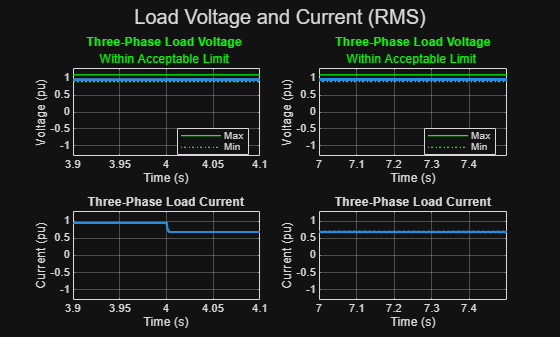

plot.loadVI(simoutData.logsout,'RMS',2);

### **Case 3 : Resynchronization**

In this scenario, the microgrid transitions from islanded operation to grid-connected mode in a controlled manner. Once the resynchronization is initiated, the microgrid controller executes the resynchronization dispatch function. The controller monitors the voltage, frequency, and phase angle at the point of common coupling (PCC), and when the micrgorid voltage, frequency, and phase angle falls with in the threshold of the grid voltage, frequency, and phase angle, the PCC breaker closes and connects the microgrid to the main grid.

Initialize the parameters for case 3 and run the model.

ResynchronizationControl;
simoutData = sim('MicrogridControl','SrcWorkspace','current');

This plot shows the active and reactive power of BESS, grid, PV, wind, and loads. Stable active power output and reactive power outputs indicate a stable control.

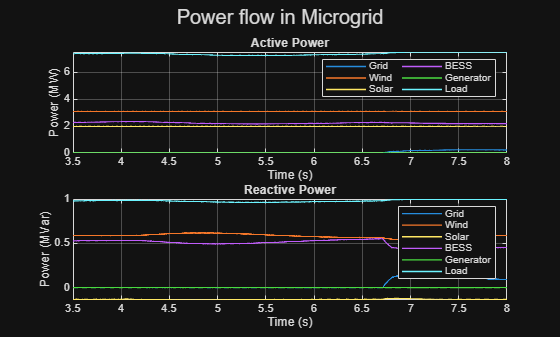

plot.powerFlow(simoutData.logsout,3);

This plot shows the resynchronization command, microgrid status, and the breaker status signals. 

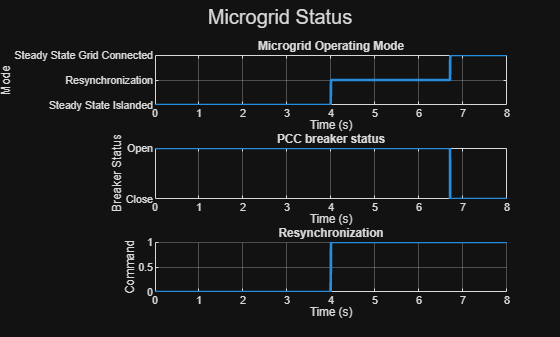

plot.microgridStatus(simoutData.logsout,3);

This plot shows the voltage and current at the loads. Stable load voltage and load during the planned islanding process indicate a stable control.

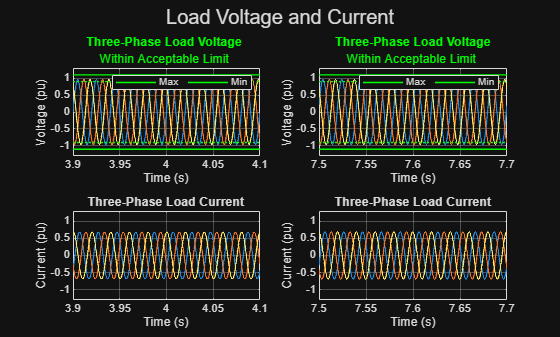

plot.loadVI(simoutData.logsout,'instantaneous',3);

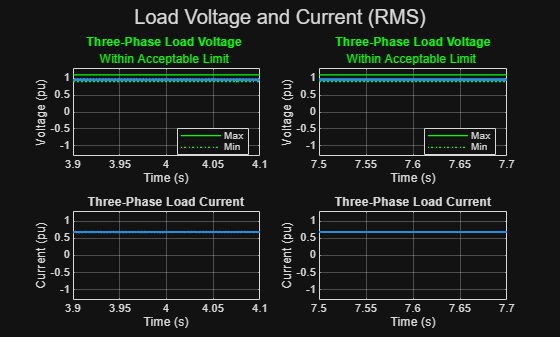

plot.loadVI(simoutData.logsout,'RMS',3);

### **Case 4 : Load and solar irradiance change in islanded mode**

This scenario demonstrates the dynamic performance of the microgrid when operating in islanded mode under varying conditions. At **4 seconds**, the system experiences a **step increase in load**, which raises the power demand. Shortly after, at **4.5 seconds**, the **solar irradiance decreases**, reducing the power contribution from the PV system. Despite these disturbances, the **Grid-Forming Battery Energy Storage System (GFM BESS)** seamlessly compensates for the deficit by increasing its active power output. The BESS maintains voltage and frequency stability throughout the event, ensuring uninterrupted supply to the loads and highlighting its capability to support the microgrid during sudden load changes and renewable generation fluctuations.

Initialize the parameters for case 4 and run the model.

LoadChange;
simoutData = sim('MicrogridControl','SrcWorkspace','current');

This plot shows the active and reactive power of BESS, grid, PV, wind, and loads. Stable active power output and reactive power outputs indicate a stable control.

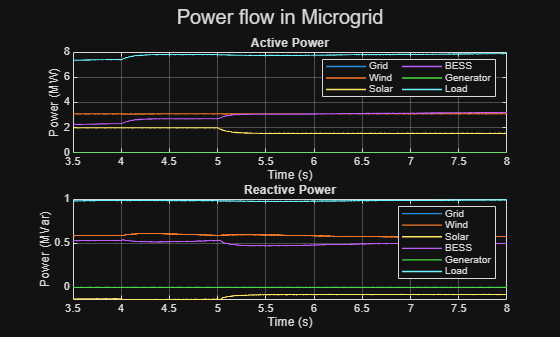

plot.powerFlow(simoutData.logsout,4);

This plot shows the microgrid status and the PCC breaker status 

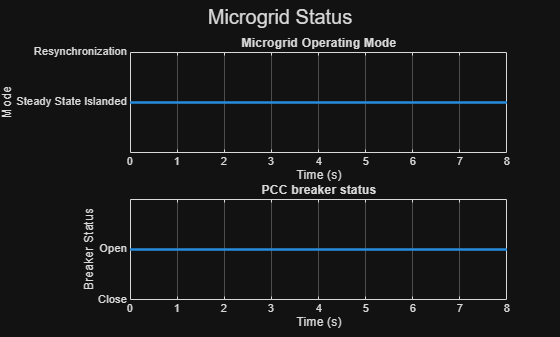

plot.microgridStatus(simoutData.logsout,4);

This plot shows the voltage and current at the loads. Stable load voltage and load during the solar insolation change and load change indicate stable control

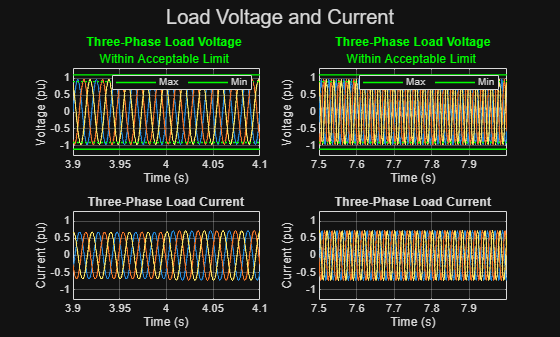

plot.loadVI(simoutData.logsout,'instantaneous',4);

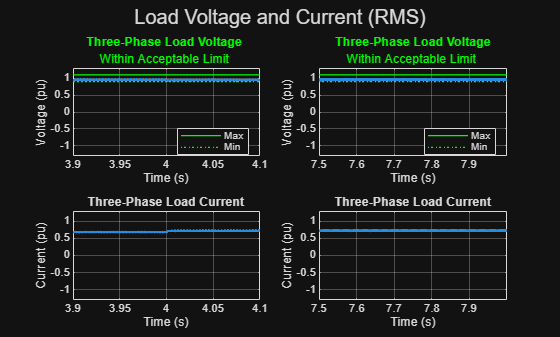

plot.loadVI(simoutData.logsout,'RMS',4);

### **Case 5 : BESS Charging in grid-connected mode**

In this scenario, the microgrid operates in **grid-connected mode** with the generator breaker open, meaning the local synchronous generator is offline. The system includes renewable sources such as **solar PV and/or wind**, which continue to supply power to the loads. The Battery Energy Storage System (BESS) is commanded to **charge from the grid**, utilizing surplus grid power while the renewables contribute to meeting the load demand. The microgrid controller coordinates power flow between the grid, renewables, and the BESS to maintain voltage and frequency stability. During this process, the load remains fully supported, and the BESS state of charge increases without causing any disturbance to the system. This scenario highlights the microgrid's capability to manage energy storage operations efficiently while integrating renewable generation and relying on the grid for additional power support.

Initialize the parameters for case 5 and run the model.

BESSCharging;
simoutData = sim('MicrogridControl','SrcWorkspace','current');

The plot illustrates the power contributions from different renewable sources alongside the Battery Energy Storage System (BESS) charging behavior while the microgrid remains grid-connected. The renewable sources such as solar PV, and wind maintain relatively stable power output throughout the period, supplying a portion of the load demand. Meanwhile, the BESS operates in charging mode, drawing power from the grid to increase its state of charge. This results in a negative power value for the BESS (indicating charging), while the renewables continue to inject positive power into the system. 

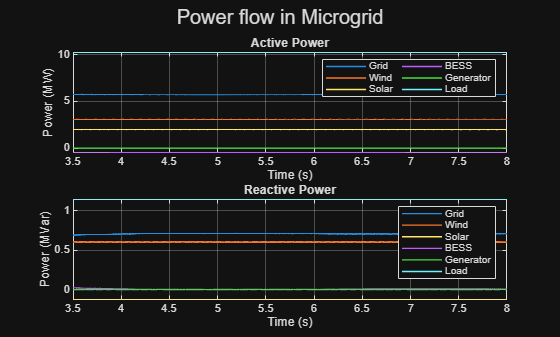

plot.powerFlow(simoutData.logsout,5);

This plot shows the microgrid status and the PCC breaker status

plot.microgridStatus(simoutData.logsout,5);

This plot shows the voltage and current at the loads. Stable load voltage and load during the BESS charging

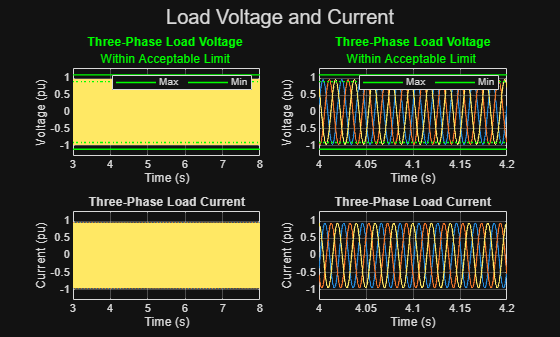

plot.loadVI(simoutData.logsout,'instantaneous',5);

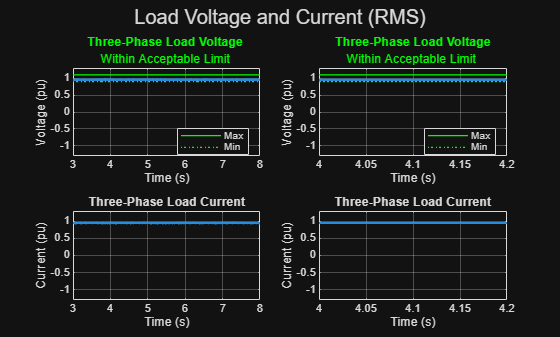

plot.loadVI(simoutData.logsout,'RMS',5);

set_param('MicrogridControl','FastRestart','off');

Copyright 2026 The MathWorks, Inc.